Bandgap and Hall Effect Lab

Steven Henderson

**Part 1: Bandgap**

Finding the bandgap of the crystals starts with,


$$\sigma =\sigma_0 e^{-\frac{E_g }{2k_B T}}$$


where $\sigma$ is conductivity. This can be derived to,


$$\ln \left(\sigma \right)=\ln \left(\sigma_0 \right)-E_g \frac{1}{2k_B T}$$


where T is measured by a thermisistor and its voltage drop,


$$T\left(k\right)=273+100V,V\;\textrm{in}\;\textrm{Volts}$$


Plotting the conductivity vs. $\frac{1}{T}$ should give a graph with the slope of $-E_g \frac{1}{2k_B }$ where we can the extrapolate$E_g$ (band gap),


$$-\textrm{slope}*2k_B =E_g$$
 

Where conductivity can be found by measuring the voltage drop and current through the crystal as,


$$\begin{array}{l}
\rho =\frac{1}{\sigma },\textrm{where}\;\rho \;\textrm{is}\;\textrm{resistivity}\\
\sigma =\frac{1}{\rho }\\
\rho =\frac{\textrm{RA}}{L}=\frac{\textrm{VA}}{\textrm{IL}}=\frac{V\left(\textrm{width}*\textrm{thickness}\right)}{\textrm{IL}}\\
R=\frac{V}{I}
\end{array}$$


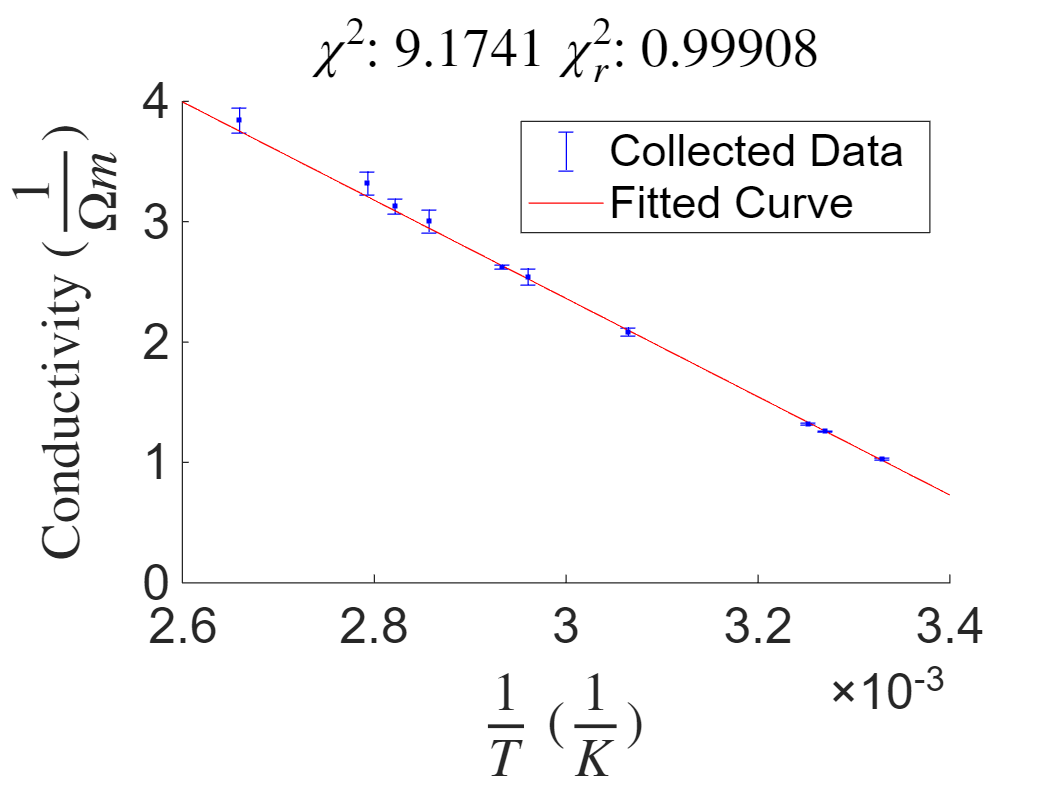

clear all; clc; clf
% Setup Data
tempV = [0.273, 0.328, 0.345, 0.533, 0.648, 0.679, 0.77, 0.814, 0.85, 1.03] ; % Voltage drop across thermisistor (V)
tempV_uncer = [0.001, 0.005, 0.001, 0.03, 0.003, 0.02, 0.005, 0.01, 0.1, 0.02] ;
V = [3.0705, 2.995, 2.9814, 2.6369, 2.3657, 2.3068, 2.0618, 1.95106, 1.8288, 1.3871] ; % Voltage drop over crystal (V)
V_uncer = [0.001, 0.0002, 0.0001, 0.008, 0.02, 0.0012, 0.01, 0.01, 0.03, 0.02] ;
I = [4.31, 5.29, 5.59, 10.66, 15.08, 16, 20.88, 22.35, 25.38, 32.48] ./ 1000; % Current across crystal (mA)
I_uncer = [0.01, 0.02, 0.04, 0.03, 0.3, 0.01, 1, 0.2, 0.05, 0.05] ; %
T = 273 + 100*tempV ; % Temperature of crystal
T_uncer = 100*tempV_uncer ; % Propagation of error
L = 20 / 1000 ; % Length (mm)
w = 10 /1000 ; % Width (mm)
thickness = 1 / 1000 ; % Thickness (mm)
resistivity = (V*w*thickness) ./ (I*L);
resistivity_uncer = sqrt(((w*thickness) ./ (I*L)).^2.*V_uncer + (log(I).*((V*w*thickness) ./ (L))).^2.*I_uncer); % Propagation of error
conductivity = log(1 ./ resistivity) ; 
conductivity_uncer = -(1 ./ resistivity).*resistivity_uncer ; % Propagation of error
% Find fit and fit slope
weights = 1 ./ conductivity_uncer.^2 ;
[f, chi] = fit((1 ./ T)', conductivity', 'poly1', 'Weights', weights) ; % NOTE: pol2 is a better fit but unable to use due to methodology
slope = f.p1 ;
slope_uncer = abs(f.p1 * 0.05);
% Plot fit and data
clf
hold on
errorbar((1 ./ T), conductivity, conductivity_uncer, 'LineStyle', 'none', 'Color', 'blue') ;
plot(f) ;
plot((1 ./ T), conductivity, 'b.') ;
hold off
set(gca, 'fontsize', 20) ;
xlabel('$\frac{1}{T}$ ($\frac{1}{K}$)', 'Interpreter', 'latex') ;
ylabel('Conductivity ($\frac{1}{\Omega m}$)', 'Interpreter', 'latex') ;
legend('Collected Data', 'Fitted Curve')
subtitle(['$\chi^2$: ', num2str(chi.sse), ' $\chi^2_r$: ', num2str(chi.rsquare)], 'Interpreter', 'latex')

% Find Bandgap
k = 8.6173303 * 10^(-5) ; % Boltzmann constant (eV/K)
bandgap = -slope*2*k ;
bandgap_uncer = slope_uncer*2*k ; % Propagation of error
disp(['Resistivity at room temp: ', num2str(resistivity(1)), ' Ohm-metres',  ' Resistivity Max: ', num2str(resistivity(end)), ' Ohm-metres'])

Resistivity at room temp: 0.35621 Ohm-metres Resistivity Max: 0.021353 Ohm-metres


disp(['Bandgap: ', num2str(bandgap), ' with an uncertainity of: ', num2str(bandgap_uncer)])

Bandgap: 0.70358 with an uncertainity of: 0.035179


**Band Gap Analysis:**

Our value of bandgap of Ge was found to be 0.7(35) eV which matches with the value found in literature which was 0.7 eV as well.

The resitivity we found for Ge at room temperature was around 0.35 which is much higher than copper which is around 1.7*10^-8 ohm-metres. This means that copper is a much better conductor than Ge as it has a lower restivity.

**Part 2: Hall Effect**

Here we are determining which crystals are n-type and which are p-type. We can start by getting the number density of carries,


$$n=\frac{\textrm{IB}}{{\textrm{qV}}_H t},\textrm{where}\;V_H \;\textrm{is}\;\textrm{Voltage}\;\textrm{due}\;\textrm{to}\;\textrm{the}\;\textrm{hall}\;\textrm{effect}\;\textrm{or}\;\textrm{the}\;\textrm{Hall}\;\textrm{Voltage}\;\textrm{and}\;t\;\textrm{is}\;t\textrm{hickness}\;\textrm{of}\;\textrm{the}\;\textrm{sample}$$


and then find the number density of positive charge carriers by,


$$p=-\frac{\textrm{IB}}{{\textrm{qV}}_H t}$$


Plotting B vs. VH will give us a slope in which should be positive for the p-type Ge and negative for n-type Ge. Using the slope we can find the number density as,


$$n=\frac{I}{\textrm{qt}}*{\textrm{slope}}^{-1}$$


% Trial 1
VH = [-15.171, -12.874, -10.536, -7.993, -4.576, 5.565, 8.144, 10.748, 12.998, 15.079] ./ 1000 ; % Hall Voltage (V)
VH_uncer = [0.001, 0.001, 0.05, 0.01, 0.01, 0.001, 0.001, 0.003, 0.02, 0.03] ;
I = [26.41, 26.41, 26.39, 26.39, 26.39, 26.4, 26.41, 26.41, 26.4, 26.4] ./ 1000 ; % Current (A)
I_uncer = [0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01] ;
B = [-0.648, -0.551, -0.457, -0.350, -0.208, 0.206, 0.312, 0.42, 0.515, 0.601] ./ 10^6 ; % Magnetic field (T)
B_uncer = [0.001, 0.001, 0.001, 0.001, 0.001, 0.001, 0.001, 0.001, 0.001, 0.001] ;
q = 6.24115*10^18 ; % Change of particle (C)
thickness = 1 ./ 1000 ; % Thickness (m)
n = (I.*B) ./ (q.*VH*thickness) ; % Number density
n_uncer = sqrt((B ./ (q*VH*thickness)).^2.*I_uncer.^2 + (I ./ (q*VH*thickness)).^2.*B_uncer.^2 + (log(VH).*((B.*I) ./ (q*thickness))).^2.*VH_uncer.^2) ; % Error propagation
disp(['Number Densities of Trial 1: ', num2str(n)])

Number Densities of Trial 1: 1.8074e-22  1.8111e-22  1.8341e-22  1.8515e-22   1.922e-22  1.5658e-22  1.6211e-22  1.6536e-22   1.676e-22  1.6859e-22


disp(['Number density uncertainities: ', num2str(n_uncer)])

Number density uncertainities: 2.7893e-19-3.547e-34i   3.2869e-19-2.2616e-34i   4.0133e-19-3.3271e-31i   5.2901e-19-6.2812e-33i   9.2404e-19-1.4167e-33i            7.6011e-19+0i             5.196e-19+0i            3.9371e-19+0i            3.2543e-19+0i            2.8052e-19+0i


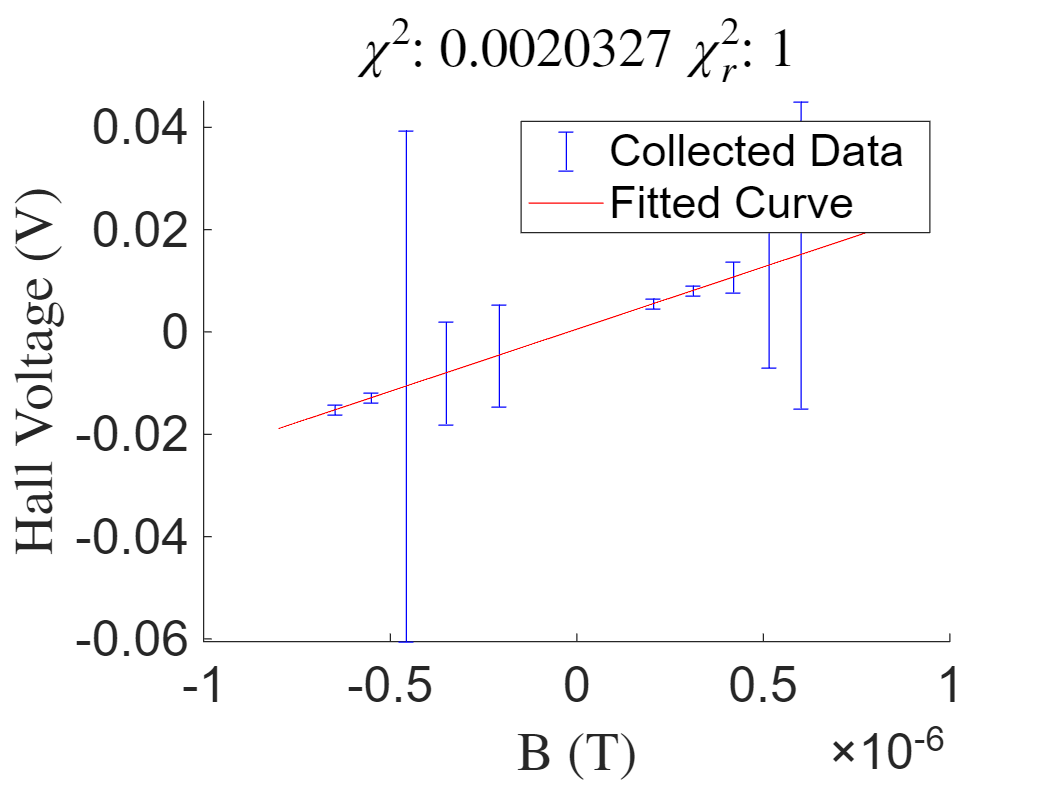

% Weights and fit
weights = 1 ./ VH_uncer.^2 ;
[f,chi] = fit(B', VH', 'poly1', 'weights', weights) ;
% Plot B vs VH
clf
hold on
errorbar(B, VH, VH_uncer, 'LineStyle', 'none', 'Color', 'blue') ;
plot(f)
hold off
set(gca, 'fontsize', 20) ;
ylabel('Hall Voltage (V)', 'Interpreter', 'latex') ;
xlabel('B (T)', 'Interpreter', 'latex') ;
legend('Collected Data', 'Fitted Curve')
subtitle(['$\chi^2$: ', num2str(chi.sse), ' $\chi^2_r$: ', num2str(chi.rsquare)], 'Interpreter', 'latex')

% Trial 2
VH2 = [1.16238, 1.16402, 1.16561, 1.16758, 1.16904, 1.17359, 1.17335, 1.17315, 1.17158, 1.16976] ; % Hall Voltage (V)
VH_uncer2 = [0.0001, 0.002, 0.002, 0.0001, 0.0001, 0.002, 0.0001, 0.003, 0.0003, 0.0005] ;
I2 = [29.2, 29.22, 29.22, 29.22, 29.21, 29.22, 29.22, 29.22, 29.21, 29.21] ./ 1000; % Current (A)
I_uncer2 = [0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01] ;
B2 = [-0.103, -0.203, -0.313, -0.408, -0.509, 0.103, 0.210, 0.327, 0.438, 0.547] ./ 10^6 ; % Magnetic field (T)
B_uncer2 = [0.001, 0.001, 0.001, 0.001, 0.001, 0.001, 0.001, 0.001, 0.001, 0.001] ;
n2 = (I2.*B2) ./ (q.*VH2*thickness) ; % Number density
n_uncer2 = sqrt((B2 ./ (q*VH2*thickness)).^2.*I_uncer2.^2 + (I2 ./ (q*VH2*thickness)).^2.*B_uncer2.^2 + (log(VH2).*((B2.*I2) ./ (q*thickness))).^2.*VH_uncer2.^2) ; % Error propagation
disp(['Number Densities of Trial 2: ', num2str(n2)])

Number Densities of Trial 2: -4.1458e-25 -8.1649e-25 -1.2572e-24  -1.636e-24 -2.0378e-24   4.109e-25  8.3793e-25   1.305e-24  1.7497e-24  2.1886e-24


disp(['Number density uncertainities: ', num2str(n_uncer2)])

Number density uncertainities: 4.025e-21  4.0221e-21  4.0166e-21  4.0099e-21  4.0035e-21  3.9893e-21  3.9901e-21  3.9908e-21  3.9948e-21   4.001e-21


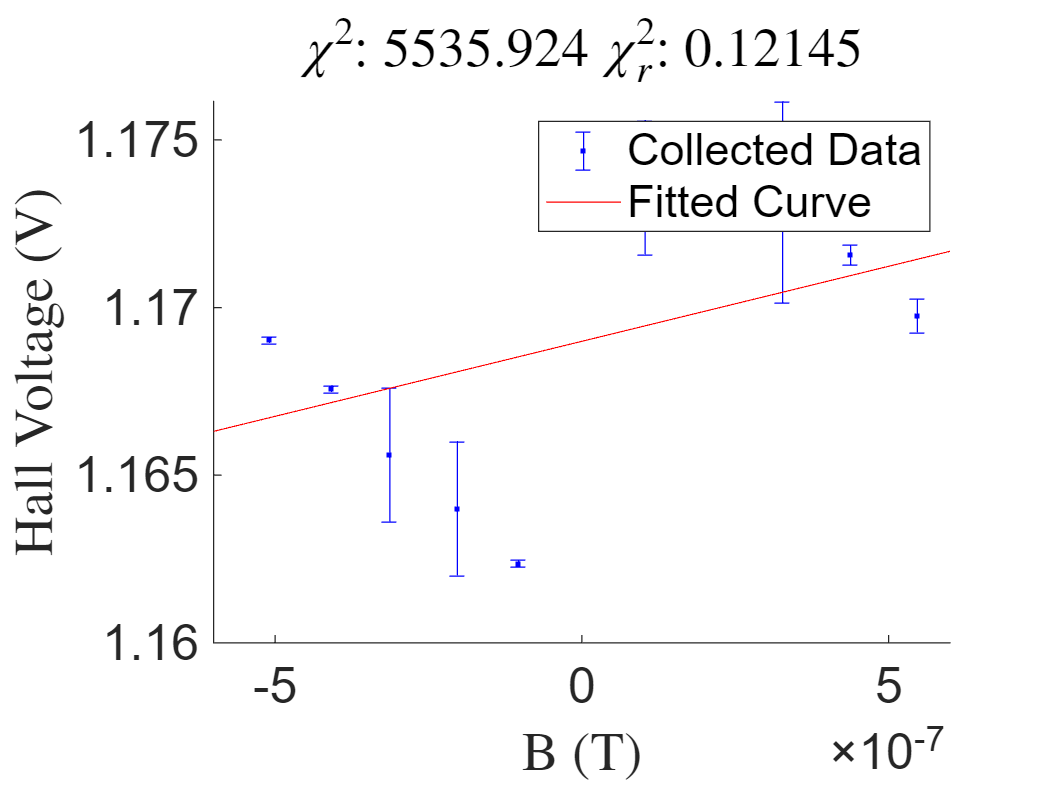

% Weights and fit
weights = 1 ./ VH_uncer2.^2 ;
[f, chi2] = fit(B2', VH2', 'poly1', 'weights', weights) ;
% Plot
clf
hold on
errorbar(B2, VH2, VH_uncer2, 'b.')
plot(f)
hold off
set(gca, 'fontsize', 20) ;
ylabel('Hall Voltage (V)', 'Interpreter', 'latex') ;
xlabel('B (T)', 'Interpreter', 'latex') ;
legend('Collected Data', 'Fitted Curve') ;
subtitle(['$\chi^2$: ', num2str(chi2.sse), ' $\chi^2_r$: ', num2str(chi2.rsquare)], 'Interpreter', 'latex') ;

**Hall Effect Analysis:**

***IMPORTANT: ****the second crystal/trial is flakey and known to give bad results which we saw*

Hall voltage depends linearly on the magnetic field which means our slope can tell us wether the crystal is n or p type. The slope does reverse if we analyize our second trial as two seperate trials and split the data into two lines that both have negative slope. This happened because the second crystal is flakey and known to give weird results.

*See code above for carrier numbers, n and n2 (First crystal, Second crystal)*

First crystal:

 - chi square: 

 - chi square reduced : 1

 - type : p

Second Crystal:

 - chi square reduced : 0.12

 - type : n 

The first crystal had a chi square reduced value of one which means that the fit line is a good fit and the data was taken well. The chi square reduced value for the second value is < 1 which means the fit may be overplotting the data or the uncertainities are overestimated.

Ge has to have lower carrier density thatn Cu which means it is a worse conductor which matches what we found in the Band Gap portion of this lab.